clear;clc;close all
layerfolder='../data/layers/';%Route to folder with ambiental data
Dimensions = ReadLayers(layerfolder); %The 19 environmental variables for all the map

----Reading layers----
Elapsed time is 9.006558 seconds.


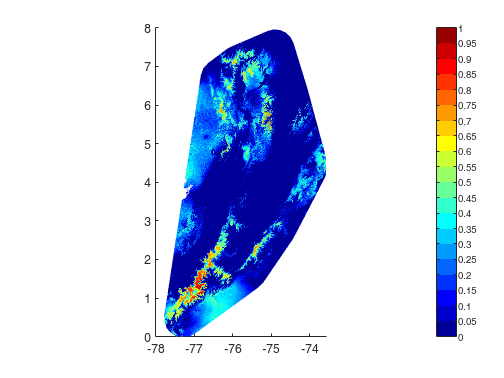

InfoInitialPoint = InitialPoint(Dimensions); %Generate a initial point to generate a niche
MapInfo = NicheGeneration(Dimensions, InfoInitialPoint, 0.5, true); %Generate the niche based on the initial point

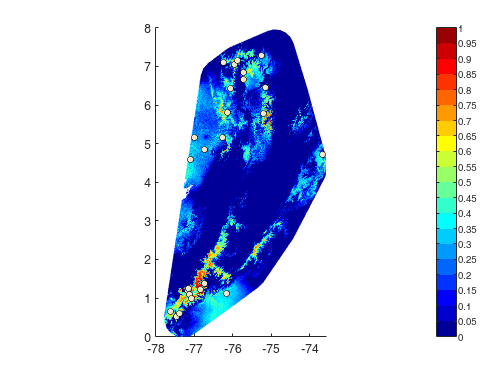

T = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 25, -3, true, 'GenSP', true, true); %Generate samples based on the generated niche

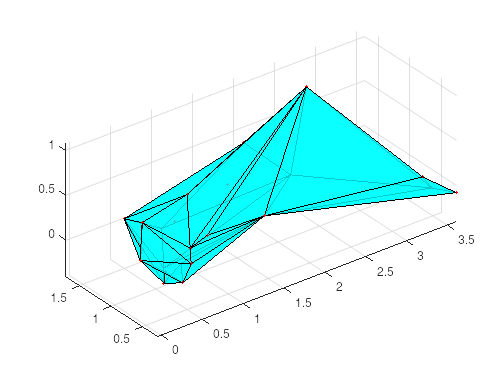

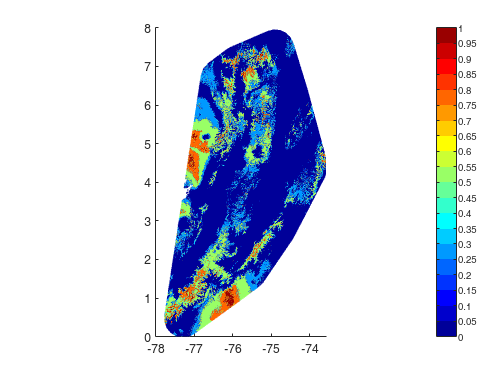

close all, clf
show=true;%show graphics
outlier=false;%remove outliers before PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers
outlier2=false;%remove outliers after PCA with method in https://github.com/AntonSemechko/Multivariate-Outliers

%ColoringBorder generates classifier object with atributes nodes = environmental variables
%for each frontier point, 
%T = table with samples and information
%readInfo = dimensions of the map
%alpha = shrinking factor

classA = ColoringBorder(T,Dimensions,1,show,outlier,outlier2); 

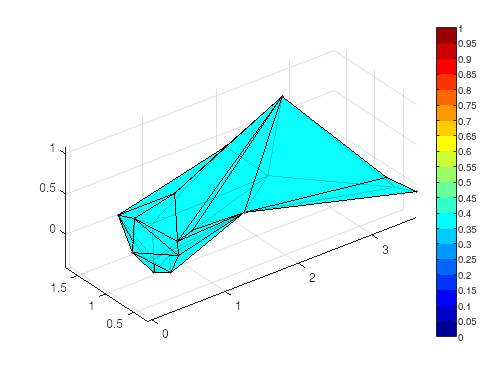

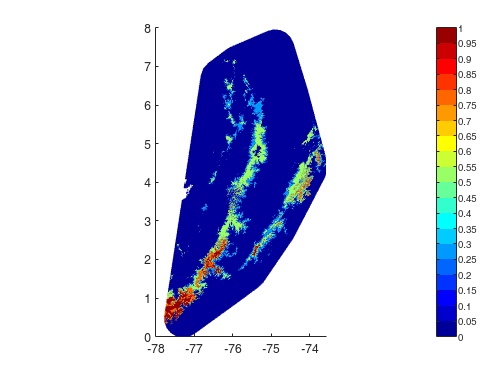

%T = table with samples and information
%readInfo = dimensions of the map
%percentile = percentile with which the radius will be taken
%alpha = shrinking factor

classB = ColoringRadius(T,Dimensions,1,25,show,outlier,outlier2); 

MapMetric(MapInfo.Map,classA.map,false) %accuracy of the generated colored map compared to the the original niche

ans =     0.8454    0.8108


MapMetric(MapInfo.Map,classB.map,false) 

ans =     0.8764    0.7742


newInfo = samplingVS(Dimensions, InfoInitialPoint, MapInfo, 100, -3, true, 'GenSP', true, true);
[dataNew,outland] = bnm_prep(newInfo, Dimensions, false, 0.7, false, false);
newPoints(dataNew{1},class)

----Finding clusters----
1 clusters identified


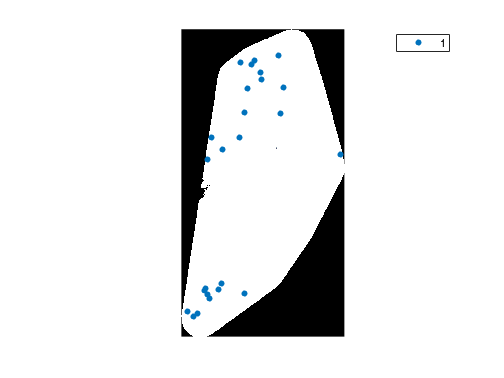

Elapsed time is 3.817956 seconds.
----Finding correlation----
Elapsed time is 5.670369 seconds.
----Creating predictors----
¡All done!
Elapsed time is 6.443157 seconds.


data = bnm_prep(T, Dimensions, false, 0.7, true, false);

dataf = bnm_modeling(data, '', false, 4, false);

----Modeling----


ij = 1

-Model 1
Elapsed time is 1.510694 seconds.


MapMetric(MapInfo.Map,dataf.Map,false) 

ans =     0.6136    0.7364


% Puntos core: 4c para el metodo hecho mal
% Calcular la distancia desde PCA3: metodo bien hecho